# Acceptable Accuracy

How accurate is enough? 

首先确定在最理想条件下，测量值围绕理论值的波动范围。即测量误差的标准差。

将测量误差标准差作为模型精度的上限目标。即回归模型的 RMSE 应该小于或接近测量误差的标准差。

这里：plateau case

结论：试验的测量值波动范围相当大。

fpath = genpath("C:\Users\regen\Documents\MATLAB\functions");
dpath = genpath("C:\Users\regen\Documents\MATLAB\Stage 6 Regression Second Try\saved data");
addpath(fpath,dpath);
load 'Stage 6 Regression Second Try'\'saved data'\'true values'\T_max_positions.mat

T_max_positions_pl = T_max_positions{end-473:end,:}

T_max_positions_pl =    38.7098
   39.4057
   38.4639
   39.5910
   38.7944
   39.5910
   39.5878
   40.4247
   39.5179
   38.3598


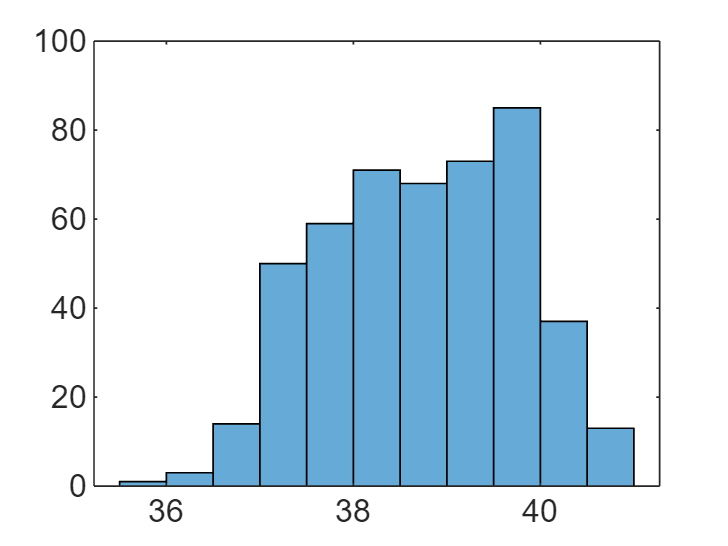

figure
histogram(T_max_positions_pl)


h_min_pl = beta_to_hmin(T_max_positions_pl,120,1.6667,0.25)

h_min_pl =    29.2330
   30.1015
   28.9286
   30.3486
   29.3377
   30.3486
   30.3444
   31.4603
   30.2511
   28.7998


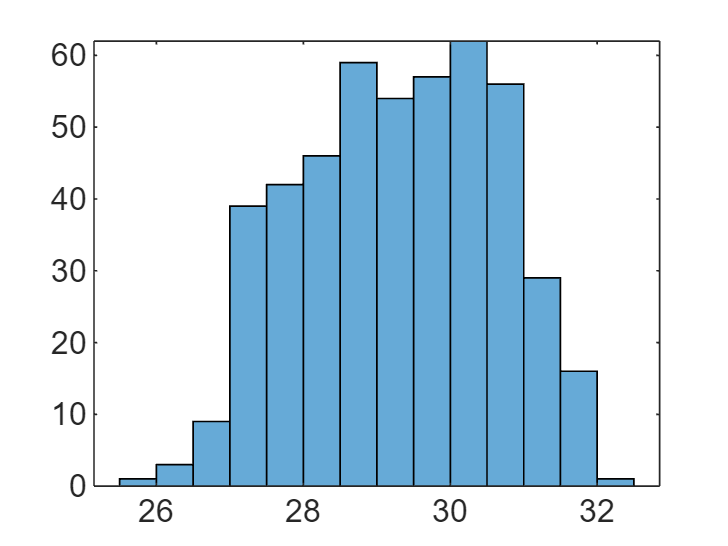

figure
histogram(h_min_pl)

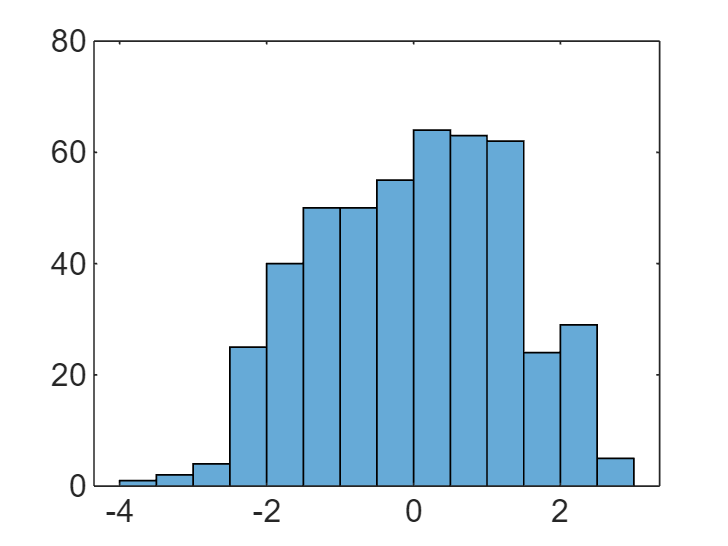


residuals = h_min_pl - mean(h_min_pl);
figure
histogram(residuals)

% |residual| < 2 的比例
disp("|Residual| < 2 的比例是："+nnz(find(abs(residuals)<2))/length(residuals)) % 0.86076

|Residual| < 2 的比例是：0.86076


disp("|Residual| < 1 的比例是："+nnz(find(abs(residuals)<1))/length(residuals)) % 0.48945

|Residual| < 1 的比例是：0.48945


### 使用不同传感器数量时，|残差| < 某个值的比例

load 'Stage 6 Regression Second Try'\'saved data'\models\bestSubset.mat
val = [1,0.6,0.3]; % 设定"某个值"

#### 不排除离群点：

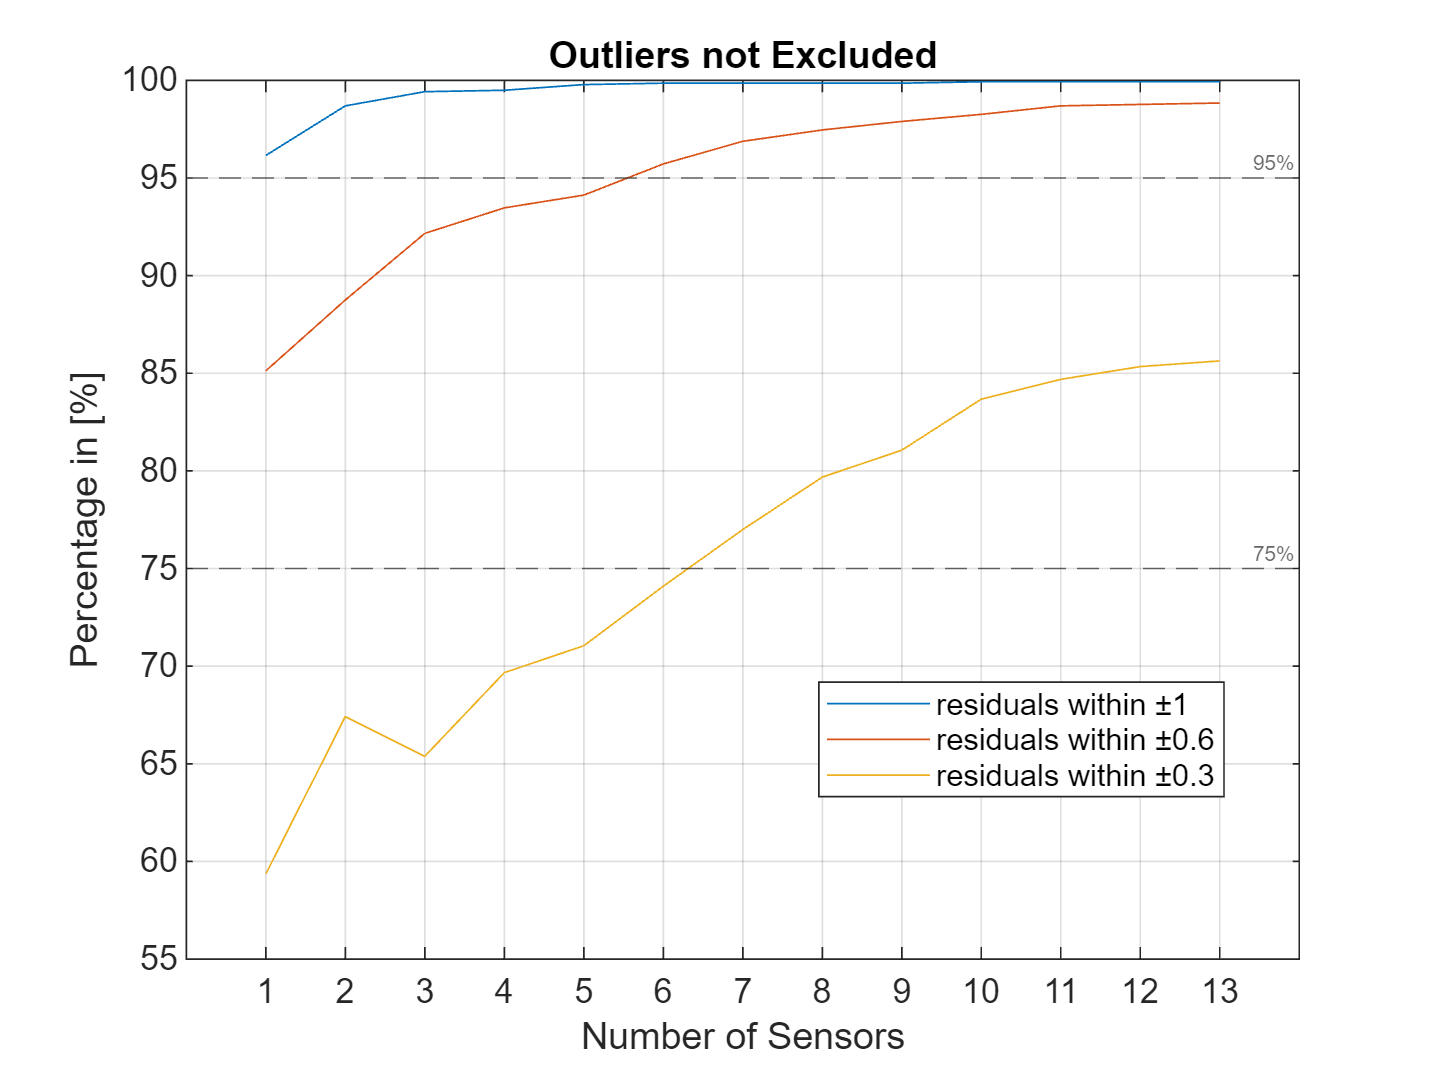

percent_with_outlier = zeros(length(val),numel(bestSubset));

for i = 1:length(val)
    for j = 1:numel(bestSubset)
        res = bestSubset(j).Residuals;
        percent_with_outlier(i,j) = nnz(find(abs(res)<val(i)))/length(res);
    end
end

当传感器数量为6个时，%的残差小于±1, %的残差小于±0.6

当传感器数量为13个时，%的残差小于±0.3

#### 排除离群点：

percent_no_outlier = zeros(length(val),numel(bestSubset));

% 储存离群点相关信息
for i = 1:numel(bestSubset)
    res = bestSubset(i).Residuals;

    

    % 计算四分位数和四分位距
    Q1 = prctile(res, 25);
    Q3 = prctile(res, 75);
    IQR = Q3 - Q1;

    % 计算离群点阈值
    lower_bound = Q1 - 1.5 * IQR;
    upper_bound = Q3 + 1.5 * IQR;

    % 返回离群点的索引和值
    outlier_indices = find(res < lower_bound | res > upper_bound);
    outliers = res(outlier_indices);
    nonoutlier_indices = find(res >= lower_bound & res <= upper_bound);
    nonoutliers = res(nonoutlier_indices);

    % 计算离群点占比
    pct = length(outlier_indices)/length(res);

    % 存入structure arrray
    residual_struct(i).outlier_idx = outlier_indices;
    residual_struct(i).nonoutlier_idx = nonoutlier_indices;
    residual_struct(i).outlier_pct = pct;
    residual_struct(i).outlier_values = outliers;
    residual_struct(i).nonoutlier_values = nonoutliers;

end
residual_struct % save as 'Stage 6 Regression Second Try'\'saved data'\models\residual_struct.mat

residual_struct = 1×13 struct array with fields:
    outlier_idx
    outlier_pct
    outlier_values
    nonoutlier_idx
    nonoutlier_values



for i = 1:length(val)
    for j = 1:numel(residual_struct)
        res = residual_struct(j).nonoutlier_values;
        percent_no_outlier(i,j) = nnz(find(abs(res)<val(i)))/length(res);
    end
end

% display information about outliers
for i = 1:numel(residual_struct)
    disp('Number of Sensors: ');
    disp(i);

    %disp('Values of Outliers:');
    %disp(residual_struct(i).outlier_values);

    %disp('Indices of Outliers:');
    %disp(residual_struct(i).outlier_idx);

    disp('Percentage of Outliers:');
    disp(residual_struct(i).outlier_pct)
end

Number of Sensors: 


     1



Percentage of Outliers:


    0.0501



Number of Sensors: 


     2



Percentage of Outliers:


    0.0450



Number of Sensors: 


     3



Percentage of Outliers:


    0.0269



Number of Sensors: 


     4



Percentage of Outliers:


    0.0152



Number of Sensors: 


     5



Percentage of Outliers:


    0.0210



Number of Sensors: 


     6



Percentage of Outliers:


    0.0196



Number of Sensors: 


     7



Percentage of Outliers:


    0.0196



Number of Sensors: 


     8



Percentage of Outliers:


    0.0189



Number of Sensors: 


     9



Percentage of Outliers:


    0.0167



Number of Sensors: 


    10



Percentage of Outliers:


    0.0203



Number of Sensors: 


    11



Percentage of Outliers:


    0.0152



Number of Sensors: 


    12



Percentage of Outliers:


    0.0167



Number of Sensors: 


    13



Percentage of Outliers:


    0.0174



只画含离群点的情况：

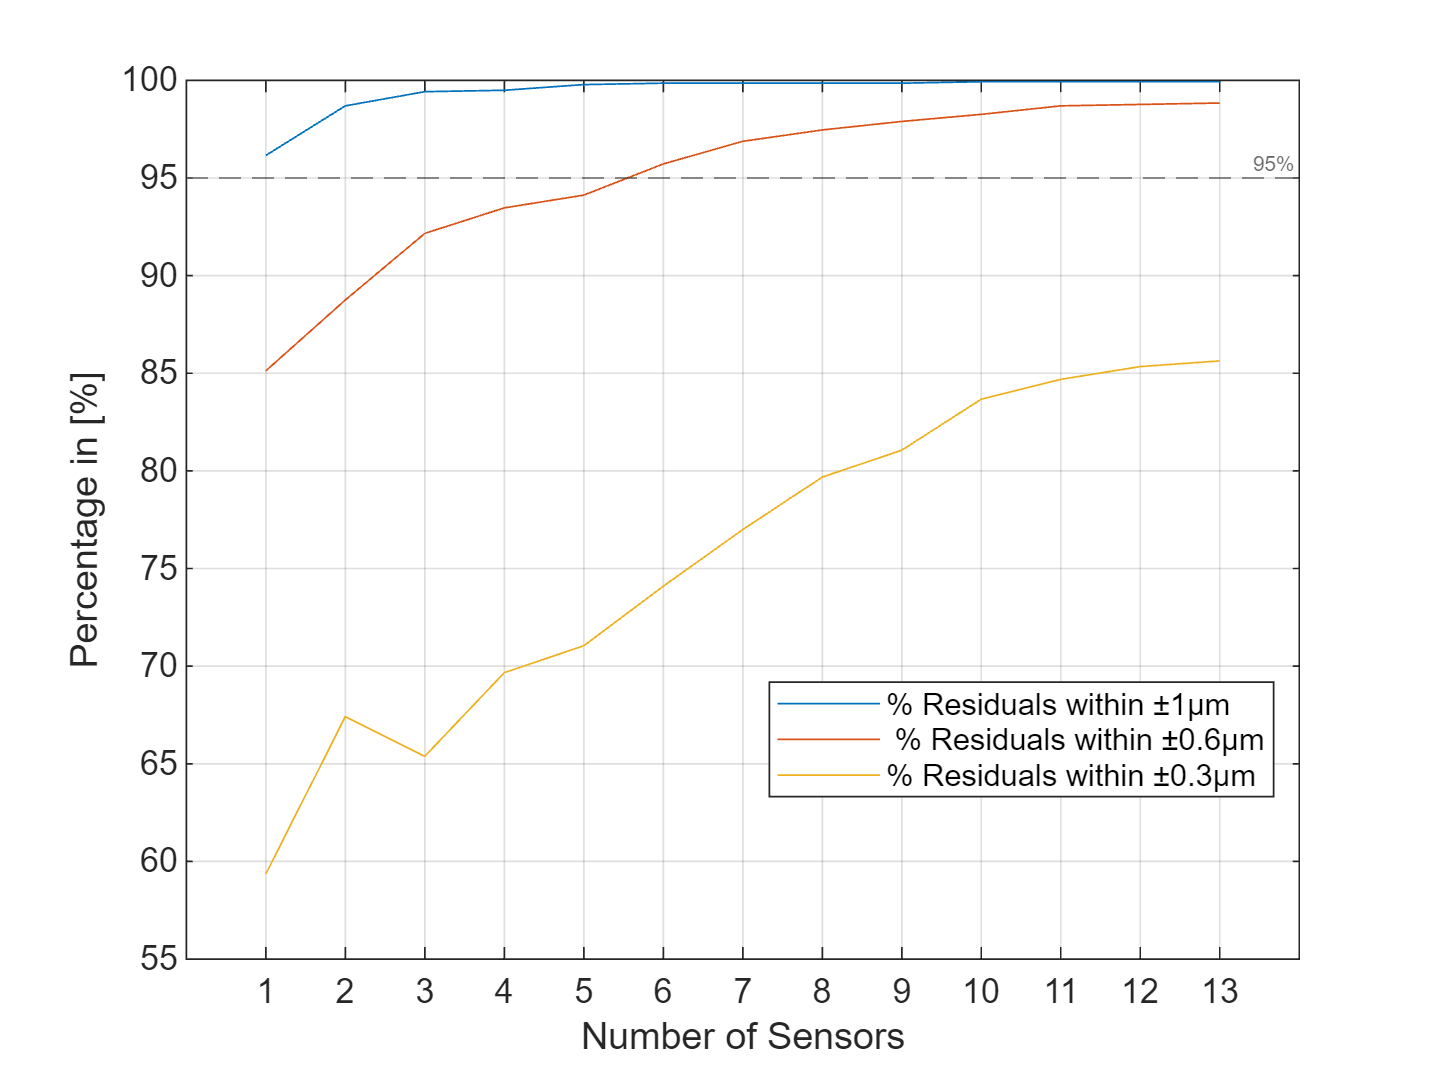

figure
plot(1:13,percent_with_outlier.*100), grid on
yline(95,'--',"95%",FontSize=6)
%yline(75,'--',"75%",FontSize=6)
xlabel("Number of Sensors"), xticks(1:13), xlim([0,14])
ylabel("Percentage in [%]")
legend("% Residuals within ±1μm"," % Residuals within ±0.6μm",...
    "% Residuals within ±0.3μm",'Location','best')

#### 并排画图对比

fig = tiledlayout(1,2,"TileSpacing","tight")

fig =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [1 2]
            Padding: 'loose'
        TileSpacing: 'tight'

  Show all properties


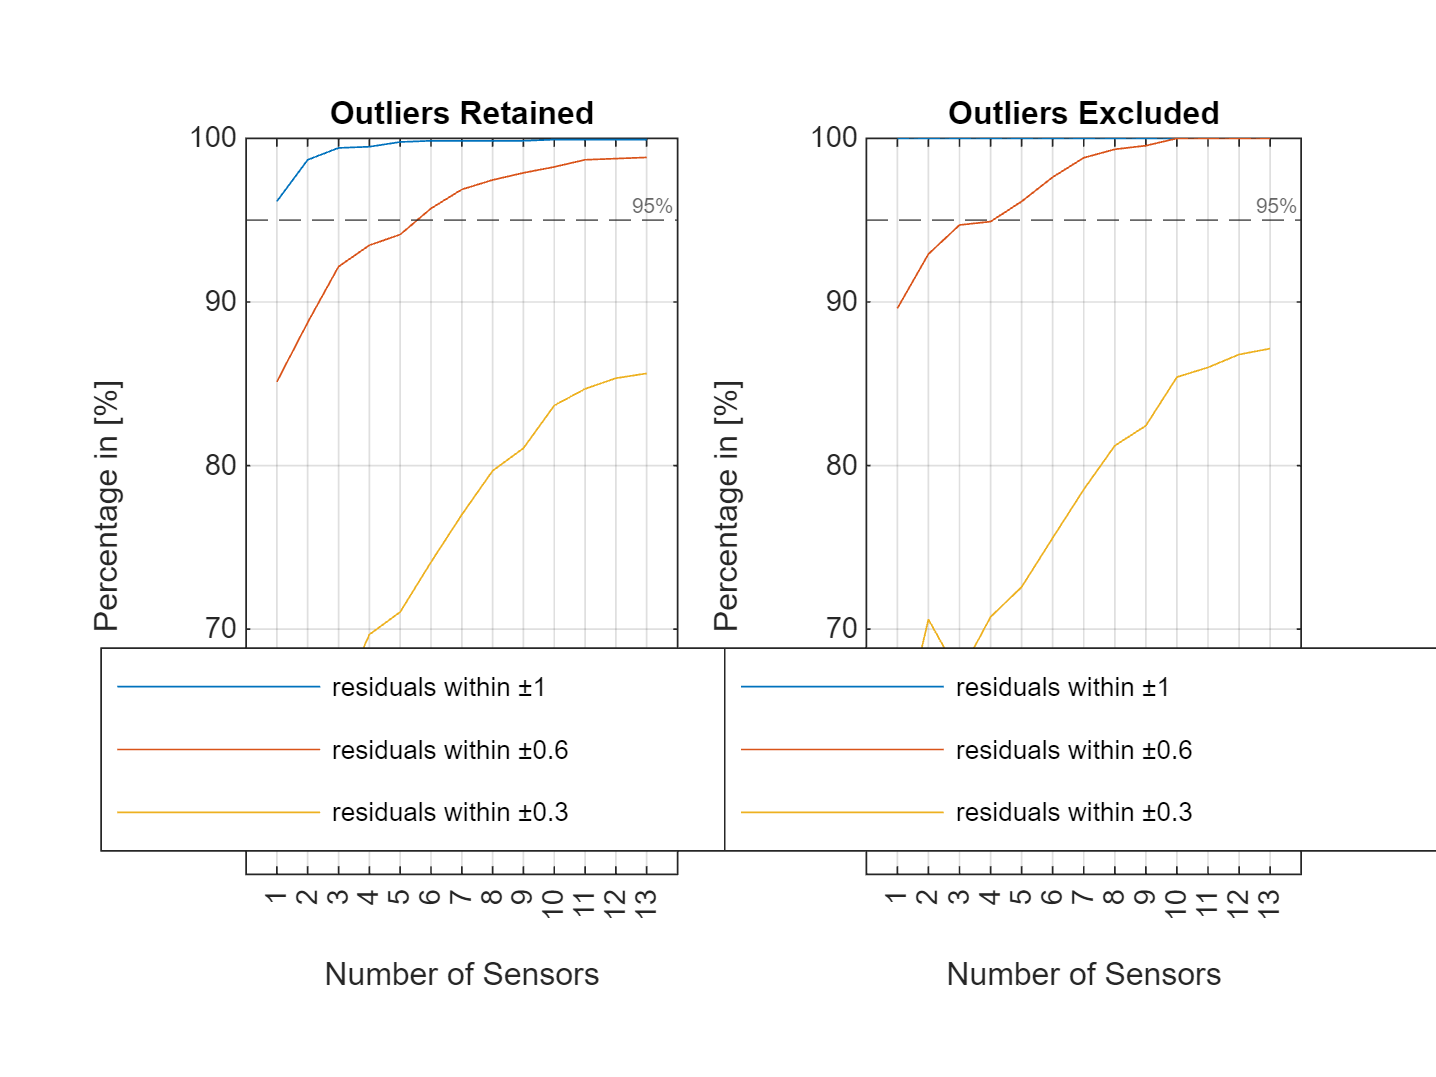


ax1 = nexttile;
plot(1:13,percent_with_outlier.*100), grid on
yline(95,'--',"95%",FontSize=6)
%yline(75,'--',"75%",FontSize=6)
xlabel("Number of Sensors"), xticks(1:13), xlim([0,14])
ylabel("Percentage in [%]")
legend("residuals within ±1","residuals within ±0.6",...
    "residuals within ±0.3",'Location','best')
title(ax1,"Outliers Retained")

ax2 = nexttile;
plot(1:13,percent_no_outlier.*100), grid on
yline(95,'--',"95%",FontSize=6)
%yline(75,'--',"75%",FontSize=6)
xlabel("Number of Sensors"), xticks(1:13), xlim([0,14])
ylabel("Percentage in [%]")
legend("residuals within ±1","residuals within ±0.6",...
    "residuals within ±0.3",'Location','best')
title(ax2,"Outliers Excluded")

linkaxes([ax1 ax2],'y');

结论：

**outliers retained: **

- 6 sensors    95.72 % within ±0.6    74.09 % within ±0.3

- 5 senosrs      94.12 % within ±0.6      71.05 % within ±0.3

- 4 senosrs     93.47 % within ±0.6     69.67 % within ±0.3

**outliers excluded: **

- 6 sensors    97.63 % within ±0.6    75.57 % within ±0.3

- 5 senosrs      96.15 % within ±0.6      72.57 % within ±0.3

- 4 senosrs    94.92 % within ±0.6    70.74 % within ±0.3

以95%左右的残差位于 ±0.6 内为标准，可以得出以下两个选择：

- outliers retained: 6 sensors

- outliers excluded: 4 sensors

处于完整性考虑，下面给出完整的表格